# Synthesis of Pipes

Parameters

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Single_Pipes
L_1=20000 um
L_1=211.98 um
L_1=2000 um
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


#### Péclet condition

Pe_cond=zeros(length(w_vec),length(l_vec));

for i_w=1:length(w_vec)

    %i_r/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Hydraulic Resistance
        % R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));
        
        %Volumetric flow
        % Q=p0/R;
        

        %Mean velocity
        %Circular channel of radius r_vec(i_r) [2, pag. 54]
        % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q/(w_vec(i_w)*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        % D_eff=D_coeff*(1+1/200*Pe^2);

        % %Péclet number, circular channel this evaluation follows [1,Eq. (4.44) pp.75]
        % Pe=r_vec(i_r)*v_char/D_coeff;
        
        %Validating the diffusion within the pipe
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            Pe_cond(i_w,i_l)=1;

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            Pe_cond(i_w,i_l)=0;
            %recording the lenght of the pipe
            if(i_w==1)
                l_vec_max_idx=i_l;
            end
            if(i_w==length(w_vec))
                l_vec_min_idx=i_l;
            end
        
        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            Pe_cond(i_w,i_l)=-1;
        end
    end
end


## Plotting the Pe_cond matrix

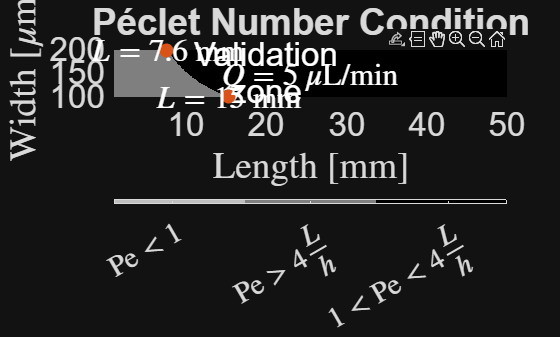

figure;

% Plot for all conditions in a single plot
hold on;
imagesc(l_vec*1e3, w_vec*1e6, Pe_cond); hold on
% colormap([0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.0072 0.4470 0.7410]); % Colors for 0, -1, and 1
colormap([0.75, 0.75, 0.75; 0.5, 0.5, 0.5; 0, 0, 0]); % Colors for 0, -1, and 1
caxis([-1 1]); % Set color axis limits to match Pe_cond values

text(20,150,{'Validation', 'zone'},'FontSize',fontsize,'Color','w','HorizontalAlignment','center');

text(l_vec(end/2)*1e3,w_vec(end/2)*1e6,{strcat('$Q=',num2str(Q*6e10,2),'\, \mu$L/min')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

%lenght and width annotations
plot(l_vec(l_vec_max_idx)*1e3, w_vec(1)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
plot(l_vec(l_vec_min_idx)*1e3, w_vec(end)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
text(l_vec(l_vec_max_idx)*1e3,w_vec(1)*1e6,{strcat('$L=',num2str(l_vec(l_vec_max_idx)*1e3,2),' $ mm')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');
text(l_vec(l_vec_min_idx)*1e3,w_vec(end)*1e6,{strcat('$L=',num2str(l_vec(l_vec_min_idx)*1e3,2),'$ mm')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

% Create a colorbar and set its ticks and labels
cb = colorbar('Ticks', [-0.7, 0, 0.7], 'TickLabels', {'$\mathrm{Pe}<1$', '$\mathrm{Pe}>4\frac{L}{h}$', '$1<\mathrm{Pe}<4\frac{L}{h}$'}, 'TickLabelInterpreter', 'latex', 'FontSize', fontsize-3,'Location','southoutside');
% cb.Layout.Tile='south';

% Set the color of the colorbar with transparency
%set(colorbarHandle, 'alpha', 0.5); % RGBA format, where A is the alpha value
%alpha(0.5);

xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 w_vec(1)*1e6 w_vec(end)*1e6])
set(gca, 'YDir', 'normal');
title('Péclet Number Condition');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

### Synthesis of pipe and biffurcation

Q_min=inf;
Q_max=-inf;

syms t

%length of the pipe
total_points=1e2;
w_vec=linspace(100e-6,200e-6,total_points);%selected based on the mixer dimenssion in [4, Fig. 3]
l_vec=linspace(16,100,total_points)*1e-3;%selected based on the Peclet number condition

%defining the time interval
total_points_time=1e2;
t_ini=1e-7;
t_end=10;
t_vector = linspace(t_ini,t_end,total_points_time);
time_sampling=t_vector(2)-t_vector(1);

h_tau=zeros(length(w_vec),length(l_vec));


for i_w=1:length(w_vec)

    % i_w/length(w_vec)*100

    for i_l=1:length(l_vec)

        %Mean velocity
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q_inlet_CNN/(w_vec(i_w)*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        D_eff=D_coeff*(1+1/200*Pe^2);      

        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            %Evaluating the peak time
            h_tau(i_w,i_l)=l_vec(i_l)/v_char-2*D_eff/v_char^2;


        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            disp(['Concentration is not constant along the x-axis, Pe=',num2str(double(Pe)),' is larger than ',num2str(4*l_vec(i_l)/height_pipe)])
            i_w
            i_l


        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            disp(['Diffusion hasn''t occurred along the axis, Pe=',num2str(double(Pe)),' is less than ',num2str(sqrt(48))])
            i_w
            i_l

        end
    end
end

### Length and width of the three pipes

%Setting the sampling time
tau_sample=2

tau_sample = 2

Design withouth biffurcations


%find the coordinates for the tau sample
%Pipe 1
[~,idx]=min(abs(h_tau(:)-tau_sample));
% Get row and column from linear index
[row, col] = ind2sub(size(h_tau), idx);
L_1=l_vec(col)

L_1 = 0.0381

w_1=w_vec(row)

w_1 = 1.2323e-04

% R_1=12*mu*L_1/(1-0.63*height_pipe/w_1)*1/(height_pipe^3*w_1);
% Q_1=p0/R_1*6e10


#### Analysis: Single Pipe

Description: This code plots the concentration at the interior of the sensor chamber

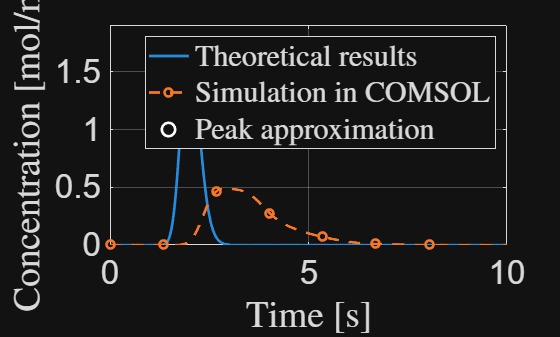

%Loading simulation results generated by the file COMSOL_Single_Pipe.mph
% Specify the CSV file
csvFileName = 'c_Pipe_1.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_1=readtable(csvFileName,opts);
t_COMSOL=(Table_c_Pipe_1.Var1);
c_COMSOL_Pipe_1=(Table_c_Pipe_1.Var2);
h_COMSOL_Pipe_1=gradient(c_COMSOL_Pipe_1,t_COMSOL);

t=0:time_delta:time_simul;


figure;
plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL,h_COMSOL_Pipe_1,'o--','LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;
plot(peak_time,h_cir_1_Theo(round(peak_time/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 t(end) 0 1.1*max(h_cir_1_Theo)]);
legend({'Theoretical results','Simulation in COMSOL','Peak approximation'},"Interpreter","latex")

#### Phase 2: Evaluating the correction of the peak time

Description: The peak correction follows the relation

$t_\text{peak}=\frac{L}{v_\text{char}}-\frac{2D}{v^2_\text{char}}$,

where the the new length is computed as

$L_\text{Phase 2}=L_1-\Delta L$,

and


$$\Delta L=\left(\Delta t_\text{peak}+\frac{2D}{v^2_\text{char}}\right)v_\text{char}$$


[~,t_peak_COMSOL]=max(h_COMSOL_Pipe_1);
t_peak_COMSOL=t_peak_COMSOL*time_delta;
delta_t_peak=t_peak_COMSOL-tau_sample,

delta_t_peak = 0.9300

delta_L=(delta_t_peak+2*D_eff/v_char^2)*v_char

delta_L = 0.0180

L_1_Phase_2=L_1-delta_L

L_1_Phase_2 = 0.0201


%Updating the value in the parameters table for COMSOL
Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_1_Phase_2, "m", "Lenght of the Pipe 1 in Phase 2");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);


#### Phase 2: Analysis 

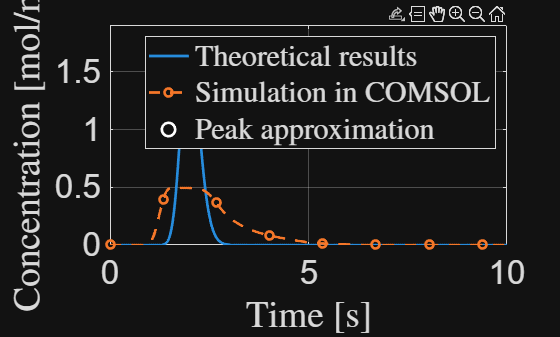


%Loading simulation results generated by the file COMSOL_Single_Pipe.mph
% Specify the CSV file
csvFileName = 'c_Pipe_1.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_1=readtable(csvFileName,opts);
t_COMSOL=(Table_c_Pipe_1.Var1);
c_COMSOL_Pipe_1_Phase_2=(Table_c_Pipe_1.Var3);
h_COMSOL_Pipe_1_Phase_2=gradient(c_COMSOL_Pipe_1_Phase_2,t_COMSOL);

t=0:time_delta:time_simul;


figure;
plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL,h_COMSOL_Pipe_1_Phase_2,'o--','LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1_Phase_2)/15):length(c_COMSOL_Pipe_1)); grid on;
plot(peak_time,h_cir_1_Theo(round(peak_time/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 t(end) 0 1.1*max(h_cir_1_Theo)]);
legend({'Theoretical results','Simulation in COMSOL','Peak approximation'},"Interpreter","latex")

#### Biffurcation

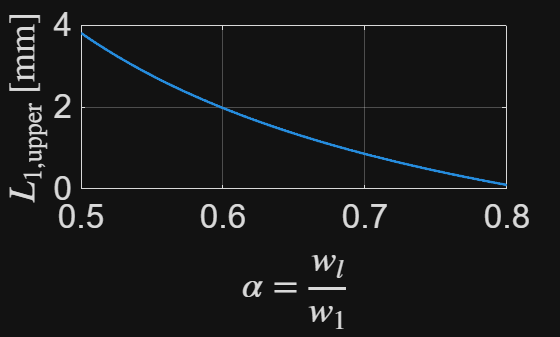

%Evaluating the flow rate
f_molecules_Phase_1=1/2; %fraction of the reduced amplitude
%fraction of the width of pipe 1
alpha_Phase_1=linspace(0.5,0.8,1000);
%length of the upper branch
L_1_upper_Phase_1=zeros(1,length(alpha_Phase_1));

L_factor=1/10;
L_1_lower=L_factor*L_1;

for i=1:length(alpha_Phase_1)
    w_1_lower_biff=alpha_Phase_1(i)*w_1;
    w_1_upper_biff=(1-alpha_Phase_1(i))*w_1;
    
    %evaluation of the length of the upper biffurcation
    L_1_upper_Phase_1(i)=f_molecules_Phase_1/(1-f_molecules_Phase_1)*L_1_lower*w_1_upper_biff/w_1_lower_biff*(1-0.63*height_pipe/w_1_upper_biff)/(1-0.63*height_pipe/w_1_lower_biff);

end

figure;
plot(alpha_Phase_1,L_1_upper_Phase_1*1e3,'LineWidth',2);grid on;
xlabel('$\alpha=\frac{w_l}{w_1}$','Interpreter','latex');
ylabel('$L_{1,\mathrm{upper}}$ [mm]','Interpreter','latex');
set(gca,'FontSize',fontsize)


%Saving the results
%Selecting one specific value for alpha
[~,idx]=min(abs(alpha_Phase_1(:)-0.7));
L_1_upper_Phase_1=L_1_upper_Phase_1(idx)

L_1_upper_Phase_1 = 8.5538e-04

alpha_Phase_1=alpha_Phase_1(idx)

alpha_Phase_1 = 0.7000


Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, f_molecules_Phase_1, "", "Factor of reduced number of molecules");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_factor, "", "Factor of Length L_1 to determine the lenght of the lower biffurcation pipe");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_1, "m", "Length of Pipe_1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, w_1, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_1_upper_Phase_1, "m", "Lenght of upper biffurcation");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, alpha_Phase_1, "", "factor of w_1 for the biffurcation");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);




%Pipe 2
[~,idx]=min(abs(h_tau(:)-2*tau_sample));
% Get row and column from linear index
[row, col] = ind2sub(size(h_tau), idx);
L_2=l_vec(col)

L_2 = 0.0839

w_2=w_vec(row);

%Pipe 3
[~,idx]=min(abs(h_tau(:)-3*tau_sample));
% Get row and column from linear index
[row, col] = ind2sub(size(h_tau), idx);
L_3=l_vec(col)

L_3 = 0.0847

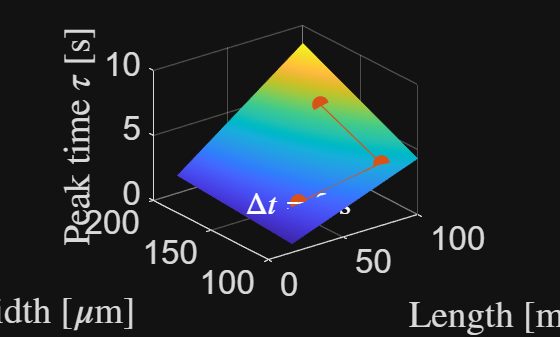

w_3=w_vec(row);


% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, w_vec*1e6, h_tau);hold on;
% Superposing the tau_coords on the plot
plot3([L_1 L_2 L_3]*1e3, [w_1 w_2 w_3]*1e6, tau_sample*[1 2 3], 'o-',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');
%annotation for the sampling time
text(L_1*1e3,w_1*1e6,tau_sample,{strcat('$\Delta t=',num2str(tau_sample,2),'$ s')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak time $\tau$ [s]','Interpreter','latex');
% title('Pipe 1')
%axis([l_vec(1)*1e3 l_vec*1e3 w_vec(1)*1e6 w_vec*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction


%Pipe 1
%Flow to the pipe 1 in a single connection
%resistance of the rectangular Pipe 1
% R_1=12*mu_Water*L_1/(1-0.63*height_pipe/w_1)*(1/(height_pipe^3*w_1))
% Q_1=p0/R_1;
% Q_1_uL_min=Q_1*6e10

%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_inlet_CNN/(w_1*height_pipe)

v_char = 0.0188


%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff

Pe = 1.3801e+03


%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2)

D_eff = 4.6667e-06

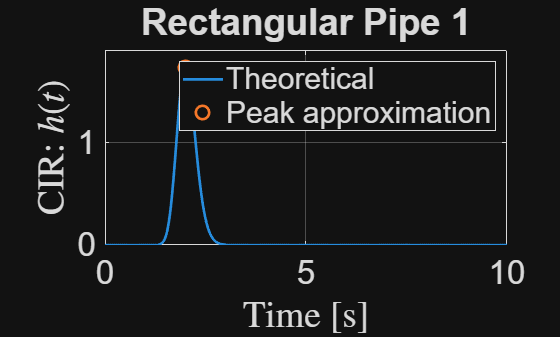


time=0:time_delta:time_simul;
%Evaluating the concentration of the straigth channel
conc_Pipe_1_Theo=1./2.*erfc((L_1-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_1_Theo=gradient(conc_Pipe_1_Theo,time);

%Approximated Peak time
peak_time=L_1/v_char-2*D_eff/v_char^2;

figure;
plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(peak_time,h_cir_1_Theo(round(peak_time/time_delta)),'o','LineWidth',2,'MarkerSize',10); grid on; hold on;
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
title("Rectangular Pipe 1")
set(gca,'FontSize',fontsize);
legend({'Theoretical','Peak approximation'},'Location','northeast');
axis([0 time(end) 0 1.1*max(h_cir_1_Theo)]);

#### Analysis

Surface concentration

Description: This code plots the concentration at the inlet of the sensor chamber

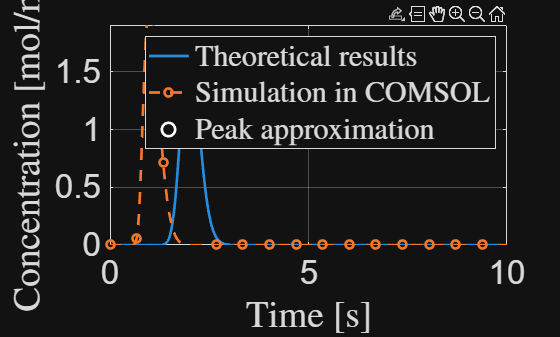

%Loading simulation results generated by the file COMSOL_Single_Pipe.mph
% Specify the CSV file
csvFileName = 'c_Pipe_1.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_1=readtable(csvFileName,opts);
t_COMSOL=(Table_c_Pipe_1.Var1);
c_COMSOL_Pipe_1=(Table_c_Pipe_1.Var2);
h_COMSOL_Pipe_1=gradient(c_COMSOL_Pipe_1,t_COMSOL);

t=0:time_delta:time_simul;


figure;
plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL,h_COMSOL_Pipe_1,'o--','LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;
plot(peak_time,h_cir_1_Theo(round(peak_time/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 t(end) 0 1.1*max(h_cir_1_Theo)]);
legend({'Theoretical results','Simulation in COMSOL','Peak approximation'},"Interpreter","latex")

Volumen concentration

Description: This code evaluates the concentration within the sensor chamber.

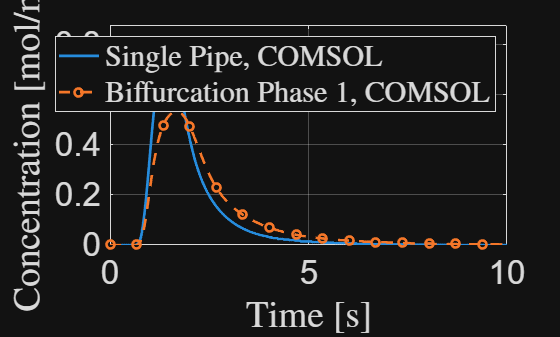


%Loading simulation results generated by the file COMSOL_Single_Pipe.mph
% Specify the CSV file
csvFileName = 'c_Pipe_1_Volumen_Phase_1.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_1=readtable(csvFileName,opts);
t_COMSOL=(Table_c_Pipe_1.Var1);
c_COMSOL_Pipe_1=(Table_c_Pipe_1.Var2);
h_COMSOL_Pipe_1=gradient(c_COMSOL_Pipe_1,t_COMSOL);

c_COMSOL_Pipe_1_Biff=(Table_c_Pipe_1.Var3);
h_COMSOL_Pipe_1_Biff=gradient(c_COMSOL_Pipe_1_Biff,t_COMSOL);

t=0:time_delta:time_simul;
figure;
% plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL,h_COMSOL_Pipe_1,'LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;  hold on
plot(t_COMSOL,h_COMSOL_Pipe_1_Biff,'o--','LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;
% plot(peak_time,h_cir_1_Theo(round(peak_time/time_delta)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 t(end) 0 1.1*max(h_COMSOL_Pipe_1)]);
legend({'Single Pipe, COMSOL','Biffurcation Phase 1, COMSOL'},"Interpreter","latex")

#### Phase 2

Description: This phase introduces corrections on the location of the peak to meet the original specifications

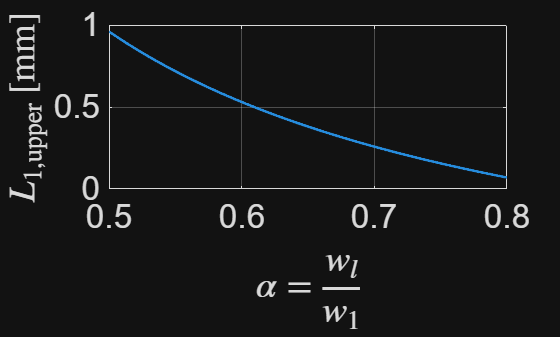

f_molecules_Phase_2=f_molecules_Phase_1-1/8;

%fraction of the width of pipe 1
alpha_Phase_2=linspace(0.5,0.8,1000);
%length of the upper branch
L_1_upper_Phase_2=zeros(1,length(alpha_Phase_2));



for i=1:length(alpha_Phase_2)
    w_1_lower_biff=alpha_Phase_2(i)*w_1;
    w_1_upper_biff=(1-alpha_Phase_2(i))*w_1;
    
    %evaluation of the length of the upper biffurcation
    L_1_upper_Phase_2(i)=f_molecules_Phase_2/(1-f_molecules_Phase_2)*L_1_lower*w_1_upper_biff/w_1_lower_biff*(1-0.63*height_pipe/w_1_upper_biff)/(1-0.63*height_pipe/w_1_lower_biff);

end

figure;
plot(alpha_Phase_2,L_1_upper_Phase_2*1e3,'LineWidth',2);grid on;
xlabel('$\alpha=\frac{w_l}{w_1}$','Interpreter','latex');
ylabel('$L_{1,\mathrm{upper}}$ [mm]','Interpreter','latex');
set(gca,'FontSize',fontsize)


%Saving the results
%Selecting one specific value for alpha
[~,idx]=min(abs(alpha_Phase_2(:)-0.7));
L_1_upper_Phase_2=L_1_upper_Phase_2(idx)

L_1_upper_Phase_2 = 2.5832e-04

alpha_Phase_2=alpha_Phase_2(idx)

alpha_Phase_2 = 0.7000


Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, f_molecules_Phase_2, "", "Factor of reduced number of molecules");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);


Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_1_upper_Phase_2, "m", "Lenght of upper biffurcation");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, alpha_Phase_2, "", "factor of w_1 for the biffurcation");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

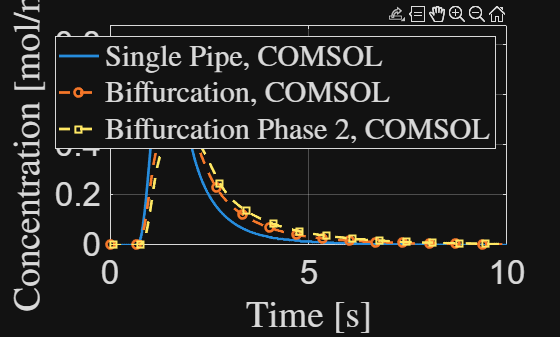

%Loading simulation results generated by the file COMSOL_Single_Pipe.mph
% Specify the CSV file
csvFileName = 'c_Pipe_1_Volumen_Phase_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
c_Pipe_1_Sensor=readtable(csvFileName,opts);
c_COMSOL_Pipe_1_Phase_2=(c_Pipe_1_Sensor.Var4);
h_COMSOL_Pipe_1_Phase_2=gradient(c_COMSOL_Pipe_1_Phase_2,t_COMSOL);

t=0:time_delta:time_simul;
figure;
% plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL,h_COMSOL_Pipe_1,'LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;  hold on
plot(t_COMSOL,h_COMSOL_Pipe_1_Biff,'o--','LineWidth',2,'MarkerIndices',1:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;
plot(t_COMSOL,h_COMSOL_Pipe_1_Phase_2,'s--','LineWidth',2,'MarkerIndices',10:ceil(length(c_COMSOL_Pipe_1)/15):length(c_COMSOL_Pipe_1)); grid on;


xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 t(end) 0 1.1*max(h_COMSOL_Pipe_1)]);
legend({'Single Pipe, COMSOL','Biffurcation, COMSOL','Biffurcation Phase 2, COMSOL'},"Interpreter","latex")

%===============Helpers========================

function writeComsolParamCSV(filename, T)
    % Writes the 3-column cell array back to CSV
    writetable(T, filename, "Delimiter", ",","WriteVariableNames", false);
end


function T = upsertParamFromVar(T, var, unit, desc)
%UPSERTPARAMFROMVAR Upsert a COMSOL parameter row using MATLAB variable name.
%
% Usage:
%   T = upsertParamFromVar(T, myVar, "mol/m^3", "Description");
%   T = upsertParamFromVar(T, myVar, "",        "Description");  % no unit

    name = inputname(2);
    if isempty(name)
        error("upsertParamFromVar: Could not infer variable name. Use upsertParamTable with explicit name.");
    end

    % If unit is omitted or passed as empty, treat as no-unit
    if nargin < 3 || isempty(unit) || (isstring(unit) && strlength(unit)==0) || ...
                     (ischar(unit) && strlength(string(unit))==0)
        unit = "";
    end

    % Desc can be omitted too
    if nargin < 4 || isempty(desc)
        desc = "";
    end

    T = upsertParamTable(T, string(name), var, unit, desc);
end


function T = upsertParamTable(T, name, value, unit, desc)
%UPSERTPARAMTABLE Insert or overwrite a parameter row (name, expr, desc)
% in a 3-column table T.

    name = string(name);

    % Normalize unit/desc robustly
    unit = normalizeTextScalar(unit);
    desc = normalizeTextScalar(desc);

    expr = buildComsolExpr(value, unit);

    % Find existing entry in first column
    idx = find(string(T{:,1}) == name, 1, "first");

    if isempty(idx)
        % Append new row (assign all columns)
        newRow = {name, expr, desc};
        T = [T; cell2table(newRow, "VariableNames", T.Properties.VariableNames)];
    else
        % Overwrite existing row
        T{idx,1} = name;
        T{idx,2} = expr;
        T{idx,3} = desc;
    end
end


function expr = buildComsolExpr(value, unit)
%BUILDCOMSOLPR Build "value[unit]" or "value" if unit is empty.

    unit = normalizeTextScalar(unit); % ensures "" if empty/whitespace/etc.

    if isnumeric(value)
        if ~isscalar(value)
            error("buildComsolExpr: value must be scalar for COMSOL parameters.");
        end
        valStr = string(num2str(value, "%.15g"));
    else
        valStr = string(value); % keep expressions as text
    end

    if strlength(unit) == 0
        expr = valStr;
    else
        expr = valStr + "[" + unit + "]";
    end
end


function s = normalizeTextScalar(x)
%NORMALIZETEXTSCALAR Convert x to a clean string scalar.
% - [] / missing / whitespace-only -> ""
% - char/string -> trimmed string scalar

    if nargin == 0 || isempty(x)
        s = "";
        return;
    end

    % Handle missing string
    if isstring(x) && isscalar(x) && ismissing(x)
        s = "";
        return;
    end

    s = string(x);
    if numel(s) ~= 1
        error("Expected a single unit/description text value, got %d elements.", numel(s));
    end

    s = strtrim(s);
    if ismissing(s)
        s = "";
    end
end


### References

[1] H. Bruus, Theoretical Microfluidics. 2008. doi: 10.1093/oso/9780199235087.001.0001.  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, "Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section," Mathematical and Computer Modelling, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: 10.1016/j.mcm.2006.11.029. 

[4] Murat paper